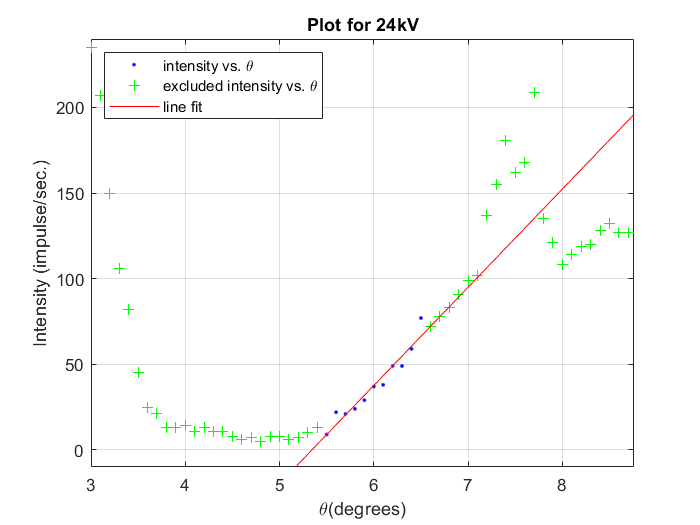

%% Fit: '24kv'.
[xData, yData] = prepareCurveData( theta24kV, Rateat24kV );

% Set up fittype and options.
ft = fittype( 'poly1' );
excludedPoints = excludedata( xData, yData, 'Indices', [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 82 83 84 85] );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', '24kv' );
h = plot( fitresult, xData, yData, excludedPoints );
legend( h, 'Rateat24kV vs. theta24kV', 'Excluded Rateat24kV vs. theta24kV', '24kv', 'Location', 'NorthEast' );
% Label axes
legend({'intensity vs. \theta','excluded intensity vs. \theta','line fit'},'Location','northwest')
title('Plot for 24kV')
xlabel('\theta(degrees)')
ylabel('Intensity (impulse/sec.)')
grid on

xlim([3.00 8.76])
ylim([-10 240])


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =        58.5  (54.11, 62.9)      \pm 2.20
 %      p2 =      -313.3  (-341.1, -285.6)   \pm 13.9

%Goodness of fit:
 % SSE: 259.9
  %R-square: 0.9817
 % Adjusted R-square: 0.9805
  %RMSE: 4.163

 %\theta_min=5.36 \pm 0.71